# Using simulink to support the study of state space systems: Part 1

The control101 toolbox focuses mainly on linear models and thus simple MATLAB code is sufficient to illustrate the core behaviours. However, the real world is full of non-linear components and characteristics such as saturations, switches and non-simple shapes. In such cases non-linear models are needed and simulink is an ideal tool to capture this. 

The study of state space systems rquires operations which are often most easily represented with block diagrams, that is simulink, rather than the precise algebra required in MATLAB m-files. This sequence of files demonstrates some simple simulink files for supporting such studies.

This file focuses on open-loop behaviour and state feedback for the nominal case.

The simulink files were made with MATLAB 2023b so may not work with earlier versions of MATLAB.

### Similar files and the toolbox

See website below for more files like this.    

[https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

### **Background on simulink**

The state space sequence does not focus on teaching simulink, but assumes familiarity and just uses the tool. Readers will be aware that there are number of settings in a simulink file, for example to define the format of input and output data. The settings and code snippets below work together, so if you change any of these settings then the code may need minor changes. A number of introductory files on simulink are available as listed next.

*myfirstsimulink_control101, intro_to_simulink_for_system_behaviour, car_suspension_simulink_control101, heating_system_simulink_control101, position_system_simulink_control101, hydraulic_system_simulink_control101, submersible_simulink_control101  *      

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Introduction the use of simulink with state space systems

- Files to support open-loop simulations

- Simple state feedback examples

- Feedforward design and simulink

## 1. Introduction to the use of simulink with state space systems

### 1.1 State space model notation

Here assume state space model of the form:


$$\dot{X} =A\;X+B\;U;\;Y=C\;X+D\;U,\;\;\;\left(1\ldotp 1\right)\;$$


with state *X*, input *U* and output *Y. *Typically this file assumes* D=0. A* typical state feedback takes the form:

$U=-K\;X$.      (1.2)

Where included, this files includes only output disturbances *d*, so the output model is modified to:


$$Y=C\;X+d$$


Where included, the observer takes the form:


$$\dot{Z} =A_m \;Z+B_m \;U+L\left(Y-Y_m \right);{\;\;\;\;Y}_m =C_m Z,\;$$


where $A_m ,B_m ,C_m \;$ are the model parameters and *Z* is the estimated value for the state *X*.  In the nominal case it is assumed that: $A_m =A,B_m =B,C_m =C$.

### 1.2 Content of this file

This file focuses on the nominal case and demonstrates simulink files to simulate a number of common but simple scenarios:

- Open loop simulation and data collection.

- Closed-loop simulation with full state feedback.

- Closed-loop simulation with feedforward.

It will be obvious from the subsections which simulink files are being used. The code snippets in this livescript define all the parameters required, run the simulation and provide the plots. The reader is reminded that the code below provides a template. In principle you can change the model parameters, and other choices, and the code should still run correctly, but now using your data.

**Remark:** Readers will be aware that there are number of settings in a simulink file, for example to define the format of input and output data. The settings and code snippets below work together, so if you change any of these settings then the code may need minor changes.

### 1.3 Further files and topics

To avoid overload in a single file, the topic of observers and integral action are in later files. ***state_space_and_simulinkfile2_control101, state_space_and_simulinkfile3_control101***.

## 2. Files to support open-loop simulations

An open-loop simulation simply simulates model (1.1) for some initial condition *X(0)* and a user choice of input *U(t)*; for simplicity the files here use *U(t)=1*, but of course readers can easily change that if desired.

The code below uses the simulink file: ***state_space_simulinkfile_openloop_control101.slx ***(see Figure 1)***.***

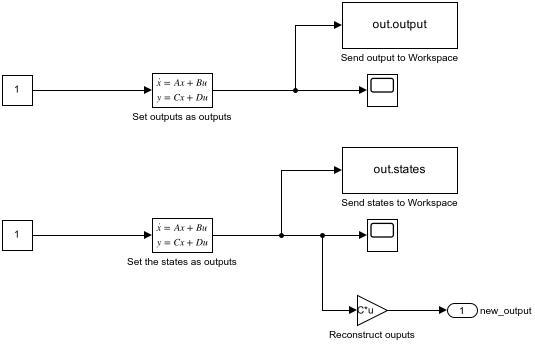

**Figure 1:** Simulink diagram for ***state_space_simulinkfile_openloop_control101.slx***

Readers will note that this has two models in parallel. One determines the outputs while the second uses a choice of *C=I* and this computes the states. Often the 2nd model is what we need when we have to utilise the values for the states elsewhere, for example where this is no observer.

disp('Section 2: Open-loop responses example 1')

Section 2: Open-loop responses


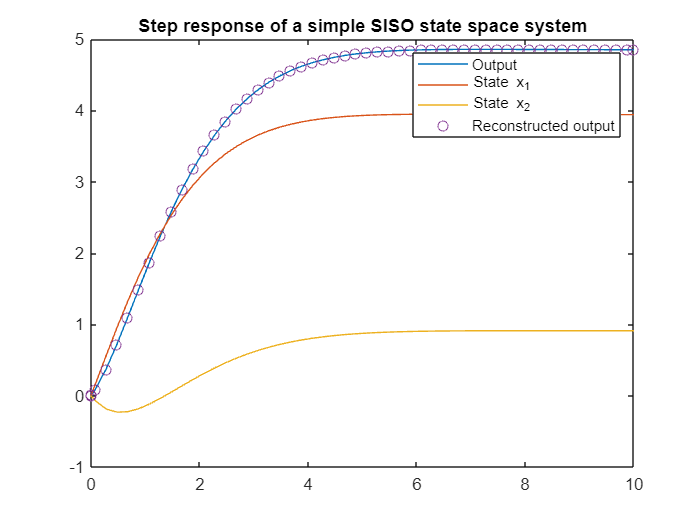

A=-[1 3;-2 5]*0.3;
B=[2;-1];
C=[1 1]; Cx = eye(2);
D=0;     Dx  =zeros(2,1);
endtime=10;

Data= sim('state_space_simulink_openloop_control101.slx');
y=Data.output.signals;
x=Data.states.signals;


plot(Data.tout,y.values,Data.tout,x.values,Data.tout,Data.yout,'o')
legend('Output','State x_1','State x_2','Reconstructed output')
title('Step response of a simple SISO state space system')


%print(['-sstate_space_simulink_openloop_control101'],'-djpeg',['state_space_simulink_openloop_control101.jpg'])

disp('Section 2: Open-loop responses example 2 (unstable)')

Section 2: Open-loop responses 2


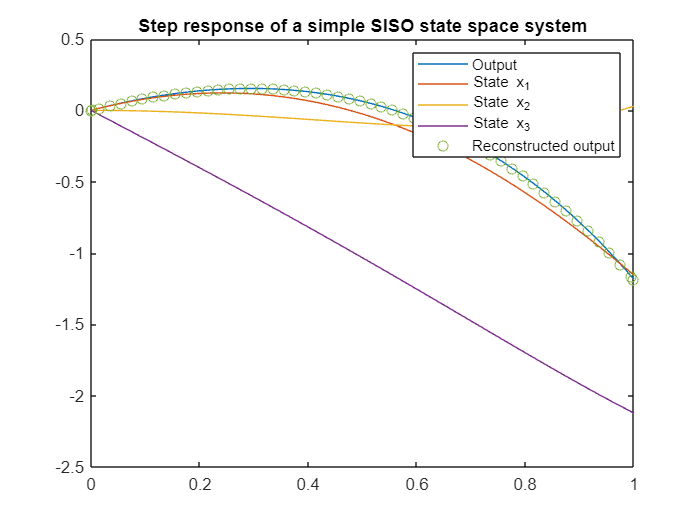

A=[0 1 2;-1 3 0;0 2 0];B=[1;0;-2];
C=[1 -1 0]; Cx=eye(3);
D=0;  Dx = zeros(3,1);
endtime=1;
Data= sim('state_space_simulink_openloop_control101.slx');
y=Data.output.signals;
x=Data.states.signals;


plot(Data.tout,y.values,Data.tout,x.values,Data.tout,Data.yout,'o')
legend('Output','State x_1','State x_2','State x_3','Reconstructed output')
title('Step response of an unstable state space system')

## 3. Simple state feedback examples

A state feedback system is given as in (1.2). More code and derivation is available in the file: ***state_feedback_control101***

The simulink diagram to capture these relationships is given in Figure 2 below. Readers will note that we have used the state space form which outputs the states, and then reconstructed the output later for display and evaluation. 

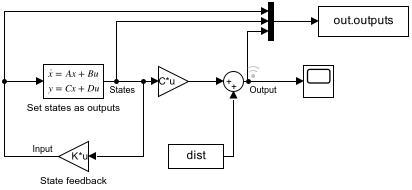

**Figure 2:** Simulink diagram for ***state_space_simulink_feedback_control101.slx***

This example/figure also demonstrates how state feedback does not utilise output measurements and thus is unaware of, and does not react to, the output disturbances. This means there will inevitably be some offset; this example is based on regulation so the target is zero. 

The code below for creating the required data and simulation outputs and the figure in the right hand window shows that when the disturbance is introduced mid-simulation, and thereafter, it is clear that the outputs are no longer converging to the origin.

disp('Section 3: Closed-loop responses with state feedback and a disturbance')

Section 3: Closed-loop responses with state feedback and a disturbance


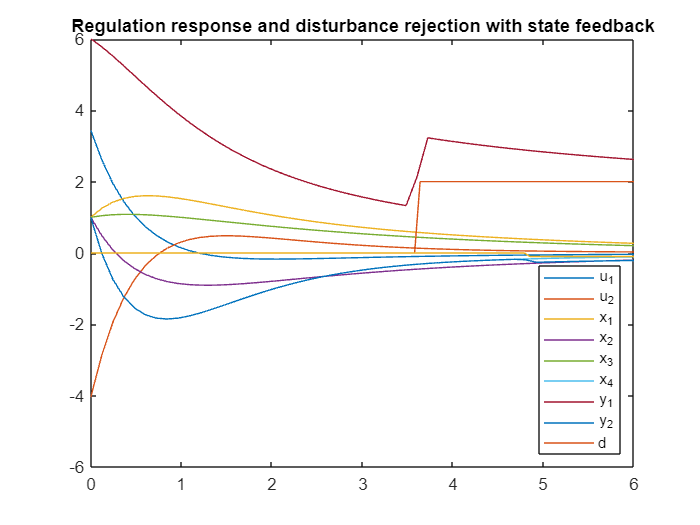

% model
A=[-0. -0.5 -0.6 0.2;0.4 1 .7 .5;-0.3 1 1 0;0.8 1.1 -0.3 0]; 
B=[1 0;-1 1;0 0.3;-1 2];
C=[3 2 1 0;0 0 0 1];   Cx=eye(4); 
D = zeros(2,2);  Dx = zeros(4,2); 
endtime = 6;

x0=[1;1;1;1];  % Initial condition

% disturbance characterisation
dist.time = linspace(0,endtime,100);
dist.signals.values = [[zeros(60,1);ones(40,1)*2],[zeros(80,1);ones(20,1)*(-0.1)]];
dist.signals.dimensions = 2;

% Control design
Q = C'*C; R=100;
K=lqr(A,B,Q,R);   % LQR
%K=place(A,B,[-0.5,-0.2,-1,-20]); % Pole placement

% Simulation 
Data = sim('state_space_simulink_feedback_control101');
z=Data.outputs.signals.values;


plot(Data.tout,z,dist.time,dist.signals.values)
legend('u_1','u_2','x_1','x_2','x_3','x_4','y_1','y_2','d','Location','southeast')
title('Regulation response and disturbance rejection with state feedback')


%print(['-sstate_space_simulink_feedback_control101'],'-djpeg',['state_space_simulink_feedback_control101.jpg'])


## 4. Feedforward design and simulink

A typical state space system with simple state feedback and feedforward is given here:

$\dot{X} =A\;X+B\;U,\;Y=C\;X,\;$  $U=-K\;X+P\;r$,   $P=-\;{\left(C{\left\lbrack A-B\;K\right\rbrack }^{-1} B\right)}^{-1}$ 

with state *X*, input *U* and output *Y *and target* r. * See ***tracking_with_statespace_control101***  for more information.

This system will ensure offset free tracking in the nominal case, but not in the presence of any uncertainty. The structure of the feedback/feedforward loop is shown in Figure 3 below.

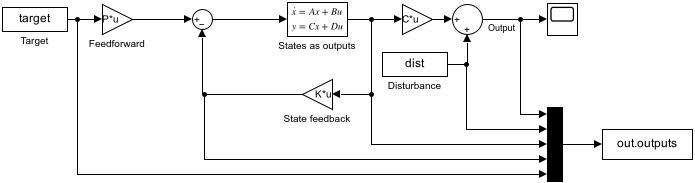

**Figure 3:** Simulink diagram for ***state_space_simulink_feedforward_control101.slx***

**Remark**: It should be emphasised that the control choices for *K,P* are done on model information ($A_m ,B_m ,C_m$). In reality this information may differ from the true system.

- There may be output disturbances so that:$\;\;\;Y=C\;X+d$

- There may be model uncertainty, so the model $\dot{X} =A_m \;X+B_m \;U;\;Y=C_m \;X$ differs from the actual process.

This section will demonstrate the efficacy of the proposed FF term with and without uncertainty and show how a suitable MATLAB file can be constructed.

### 3.1. Example showing the nominal case and the impact of output disturbances

One can easily validate that the system tracks accurately when there are no disturbances by setting the disturbance values to zero in the code below.

disp('Section 3.1: Closed-loop responses with feedforward and feedback')

Section 3.1: Closed-loop responses with feedforward and feedback


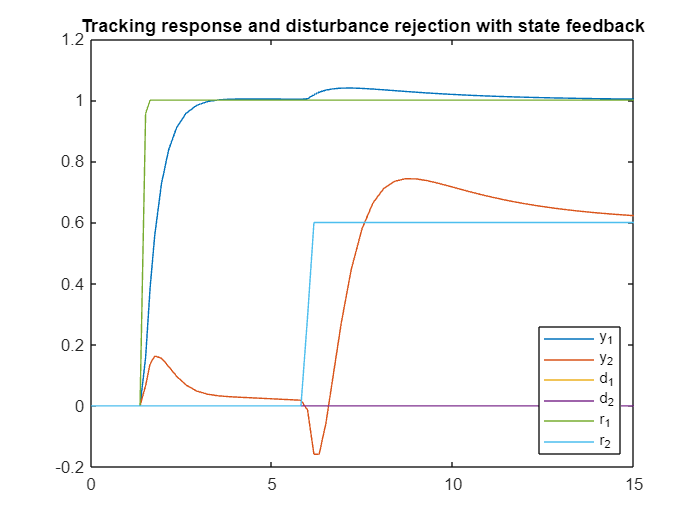

% model
A=[-0. -0.4 -0.6 0.2;0.4 1 .7 .5;-0.3 1 1 0;0.8 1.1 -0.3 0]; 
B=[1 0;-1 1;0 0.3;-1 2];
C=[3 2 1 0;0 0 0 1]; Cx=eye(4); 
D = zeros(2,2); Dx = zeros(4,2); % to extract the states
endtime=15;

%% Control design
Q = C'*C; R=1;
K=lqr(A,B,Q,R);
P = -inv(C*inv(A-B*K)*B);

%% disturbance and target characterisation
dist.time = linspace(0,endtime,100);
dist.signals.values = [[zeros(60,1);ones(40,1)*0.2],[zeros(80,1);ones(20,1)*(-0.1)]];
dist.signals.dimensions = 2;
target.time = dist.time;
target.signals.values = [[zeros(10,1);ones(90,1)*1],[zeros(40,1);ones(60,1)*0.6]];
target.signals.dimensions = 2;

Data = sim('state_space_simulink_feedforward_control101');
z=Data.outputs.signals.values;

figure
plot(Data.tout,z(:,[1,2,3,4,11,12]))
legend('y_1','y_2','d_1','d_2','r_1','r_2','Location','southeast')
title('Tracking response and disturbance rejection with state feedback')

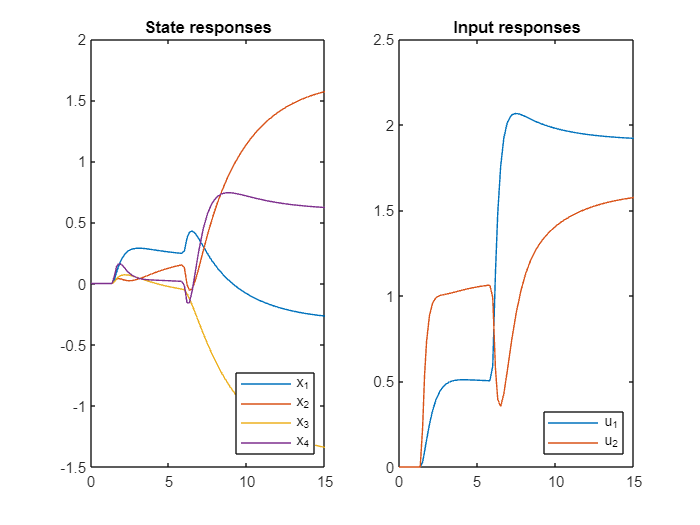



figure
subplot(121)
plot(Data.tout,z(:,[5:8]))
legend('x_1','x_2','x_3','x_4','Location','southeast')
title('State responses')

subplot(122)
plot(Data.tout,z(:,[9:10]))
legend('u_1','u_2','Location','southeast')
title('Input responses')


%print(['-sstate_space_simulink_feedforward_control101'],'-djpeg',['state_space_simulink_feedforward_control101.jpg'])

### 3.2 Example showing the impact of parameter uncertainty

In order not to confuse the effects, the disturbance signal is set to zero in this example, but readers can easily re-instate by modifying the values in the code below.  It is clear that the targets are not tracked with zero offset in this example.

disp('Section 3.2: Closed-loop responses with feedforward and feedback and parameter uncertainty')

Section 3.2: Closed-loop responses with feedforward and feedback and parameter uncertainty


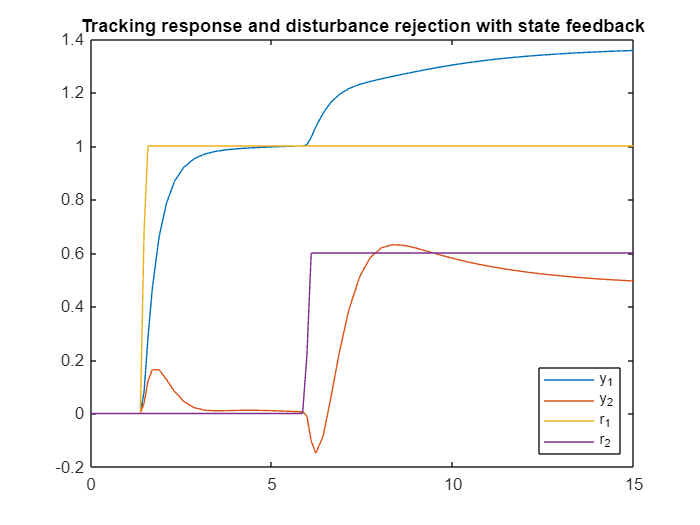


% Real process - values used in simulink simulation
A=[-0. -0.4 -0.6 0.2;0.4 1 .7 .5;-0.3 1 1 0;0.8 1.1 -0.3 0]; 
B=[1 0;-1 1;0 0.3;-1 2];
Csimulink=eye(4); Dsimulink = zeros(4,2); % to extract the states
C=[3 2 1 0;0 0 0 1];

% model - values used in controller design
Am=[-0. -0.4 -0.6 0.21;0.42 1 .7 .5;-0.3 1.05 1 0;0.82 1.1 -0.31 0]; 
Bm=[1.2 0;-1.1 1;0 0.4;-1 2];
Cm=[3 2.1 1.4 0;0 0 0 1.2];
Dm = zeros(2,2);

% disturbance and target characterisation
dist.time = linspace(0,endtime,100);
dist.signals.values = 0*[[zeros(60,1);ones(40,1)*0.2],[zeros(80,1);ones(20,1)*(-0.1)]];
dist.signals.dimensions = 2;
target.time = dist.time;
target.signals.values = [[zeros(10,1);ones(90,1)*1],[zeros(40,1);ones(60,1)*0.6]];
target.signals.dimensions = 2;

% Control design
Q = Cm'*Cm; R=1;
K=lqr(Am,Bm,Q,R);
P = -inv(Cm*inv(Am-Bm*K)*Bm);

% Run simulation
Data = sim('state_space_simulink_feedforward_control101');
z=Data.outputs.signals.values;

% Plotting
figure
plot(Data.tout,z(:,[1,2,11,12]))
legend('y_1','y_2','r_1','r_2','Location','southeast')
title('Tracking response and disturbance rejection with state feedback')

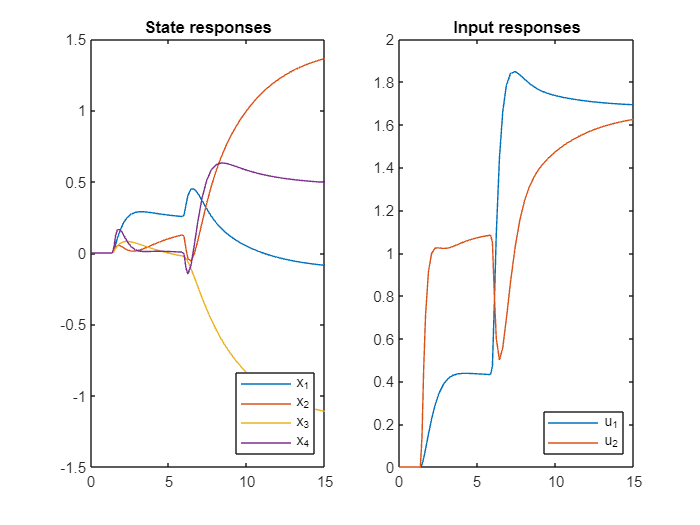


figure
subplot(121)
plot(Data.tout,z(:,[5:8]))
legend('x_1','x_2','x_3','x_4','Location','southeast')
title('State responses')

subplot(122)
plot(Data.tout,z(:,[9:10]))
legend('u_1','u_2','Location','southeast')
title('Input responses')